# UFME7R-15-M Robot Learning for Control

## Written Report Template: Develop a Method for Planar Robot Manipulation

clearvars

### How do I use this file?

This MLX file serves as the template for your main coursework submission. Please read the assessment brief on Blackboard and complete this MLX file along with the class files `SkillGeneralisation.m``, ``MixtureGaussian.m`, and the Simulink project **RobotSimulation.slx **to produce a complete submission. To ensure the code in this MLX runs correctly, you must complete the required functions within `SkillGeneralisation.m`, `MixtureGaussian.m`, and `RobotSimulation.slx`. Please read the instructions carefully before starting your work.

Your final submission should include a **PDF export **of your MLX file, as well as a **compressed ZIP** file containing your complete working workspace, including the finished MLX file, all your code, and any data used to support your written report. Please note that the final marking will be based on the PDF **only**, so make sure that everything required is fully included in the PDF document. If you are unsure how to use an MLX file or how to export it for submission, please refer to the guide available on Blackboard Ultra.

If you are comfortable writing MATLAB functions and wish to use them to organise your code, please define them as **static functions/methods** inside `SkillGeneralisation.m` rather than creating additional standalone files. If this is not possible for any reason, you may include the additional files in your submission.

Please also note the following:

- Ensure you are using a MATLAB version of R2025b or newer, and that both Simulink and Simscape are installed.

- There are some outputs in the template, which are used as reference. Please delete them before you start to add your content.

- Your PDF exported from this MLX will be marked and checked with your completed class files. Your MATLAB files are used to support what you have documented in the PDF, but will not be marked themselves.

- Very wide images do not render well onto the PDF. Please check to make sure images you insert are captured appropriately within the PDF.

## Task 1: Introduction (5 marks)

- Utilise Dynamic Movement Primitives (DMPs) alongside Gaussian Mixture Models (GMM) and Gaussian Mixture Regression (GMR) to devise an enhanced Dynamic Movement Primitives for single-arm robot manipulation.

- During the development of the new algorithm, you can refer to the paper "DMP and GMR based Teaching by Demonstration for a KUKA LBR Robot" by Hewitt et al., introduced in the lecture.

- Write an introduction about the calculation steps based on your understanding of this paper, into your own report.

- Please ensure that the algorithms you introduce are consistent with the robot‑learning implementation in Task 2.

#### *Useful materials for this Part include:*

- Lecture notes on DMPs

- Lectures on Linear model, GMM and GMR

- Describe your calculations below (max 200 words):

#### Describe your calculations below (max 200 words):

--------------------------------------------------------

This project develops an enhanced DMP method for single-arm manipulation by combining Dynamic Movement Primitives with GMM-GMR regression. First, multiple demonstrated Cartesian trajectories are resampled and converted into position, velocity and acceleration. The canonical system generates a phase variable $s$, and the original DMP is used to calculate the nonlinear forcing term:


$$f(s)=\frac{\ddot{x}-\beta(g-x)+\alpha\dot{x}}{s}$$


This forcing term represents the shape information of the demonstrated motion. In the original DMP, it is fitted using locally weighted regression. To improve generalisation from several demonstrations, the enhanced method models the joint distribution $P(s,f)$ using a Gaussian Mixture Model. The GMM parameters, including priors, means and covariance matrices, are learned using the EM algorithm. Gaussian Mixture Regression is then applied to estimate the expected forcing term $\hat{f}(s)$ for each phase value. Finally, the regressed forcing term is inserted back into the DMP transformation system to reconstruct the trajectory. This follows the idea of using GMM-GMR to generate a smoother synthesized path from multiple imperfect demonstrations, as described in the KUKA LBR teaching-by-demonstration study. 

--------------------------------------------------------

## Task 2: Robot Learning (20 marks total) 

Implement your improved DMP method using the following steps:

### Part 1: Original DMPs (3 marks)

- Employ the original DMP to compute the values of nonlinear term (the forcing term) of the inputs.

- Generate more plots to demonstrate the trajectories reconstructed by the DMPs with different parameters.

#### *Useful materials for this Part include:*

- Lecture notes on DMPs

- Exercise for DMPs

- Documentation for loading data into MATLAB: [https://uk.mathworks.com/help/matlab/ref/load.html](https://uk.mathworks.com/help/matlab/ref/load.html) 

The below code provides a starting point for Part 1. You need to complete the functions in the `SkillGeneralisation.m` to make the code work.

Dataset parameters

nbData = 200;               % Length of each demo trajectory 
nbDemos = 5;                % Number of demonParagraph The below code provides a starting point for Part 1. You need to complete the functions in the SkillGeneralisation.m to make 


nStates = 25;                % Number of activation functions (i.e., number of states in the forcing term)
nVar = 3;                   % Number of variables [s,f1,f2] (decay term and perturbing force)
beta = 50;                  % Stiffness gain (β)
alpha = (2*beta)^.3;        % Damping gain (with ideal underdamped damping ratio) (α)
decayFactor = 1.1;          % Decay factor (a in τx'=-ax)
dt = 0.01;                  % Duration of time step (τ)

Load handwriting trajectories

demos = [];
load('Demonstrations.mat');
demos_in = {demos{1:nbDemos}};

Initialise the DMP instance

dmp = SkillGeneralisation(nVar, nStates, beta, alpha, dt);   % Class constructor
dmp = dmp.canonicalSystemInitialisation(decayFactor, nbData);
dmp = dmp.trajectort2Forcing(demos_in);

Regression with Locally Weighted Linear Regression (WLR)

fWLR = dmp.fittingWithLocallyWLS();
trajWLR = dmp.forcing2Trajectory(fWLR);

Spatial plot

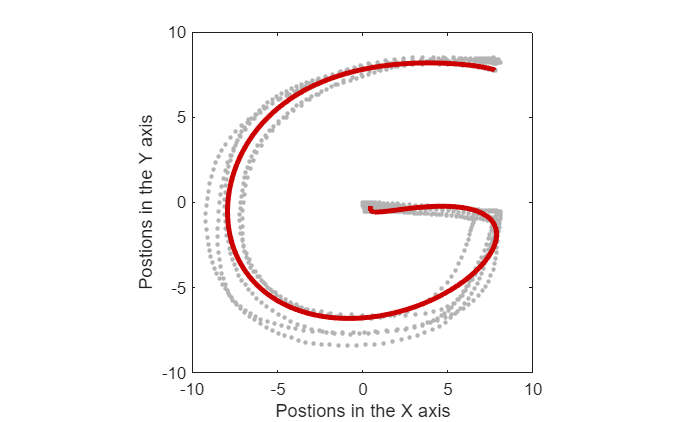

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajWLR(1,:),trajWLR(2,:),'-','linewidth',3,'color',[.8 0 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
axis equal; axis square; 

--------------------------------------------------------

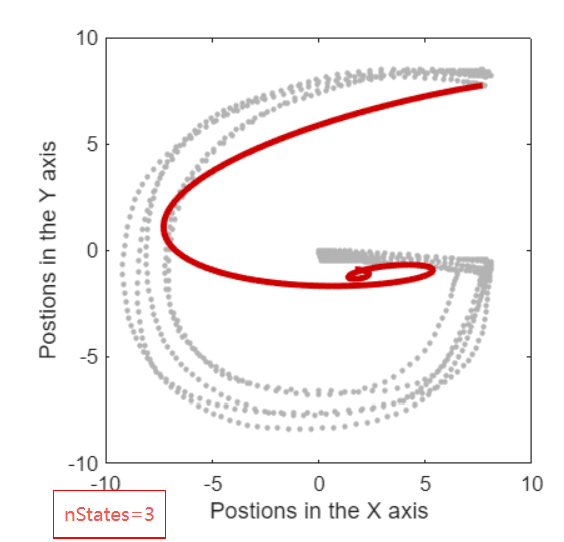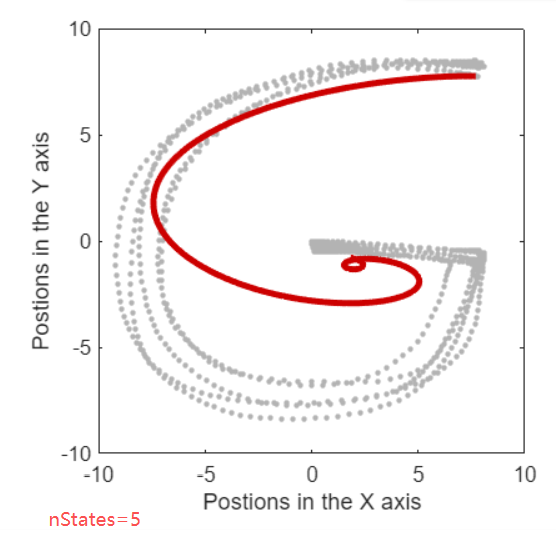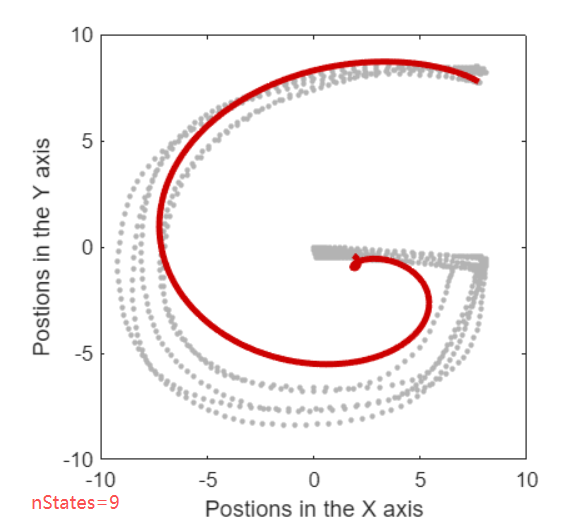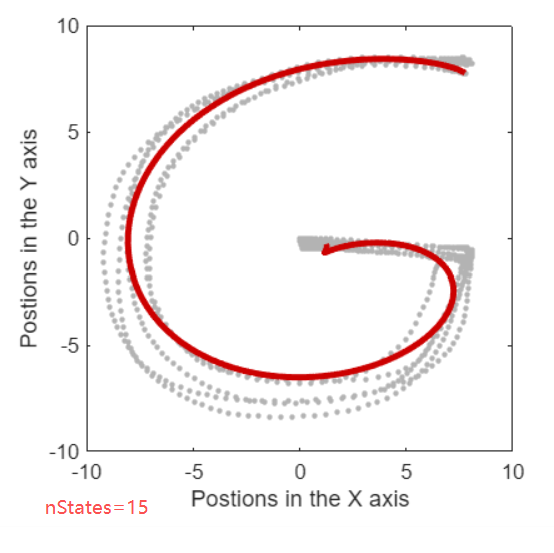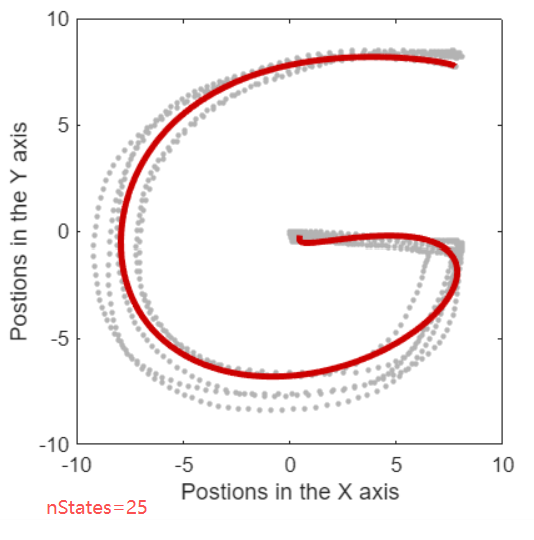

--------------------------------------------------------

### Part 2: GMM-GMR enhanced DMPs (2 marks)

- Utilize Gaussian Mixture Models (GMM) and Gaussian Mixture Regression (GMR) instead of conventional Locally Weighted Linear Regression (WLR) to calculate the trajectory.

- Add figures to present your learning and regression results, including but not limited to: 1) the GMM components fitted to the trajectories, 2) the log‑likelihood curve over the GMM fitting iterations, and 3) the reconstructed trajectories alongside the demonstrations.

#### *Useful materials for this Part include:*

- Lecture notes on GMM and GMR

- Lab tutorial notes on GMM and GMR

The below code provides a starting point for Part 2. You need to complete the functions in the `MixtureGaussian.m` to make the code work.

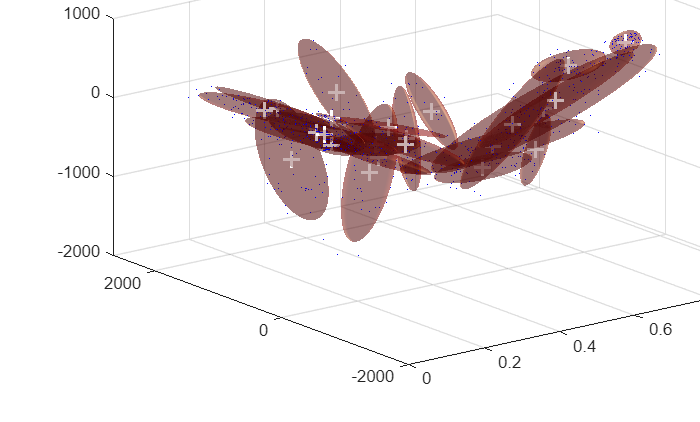

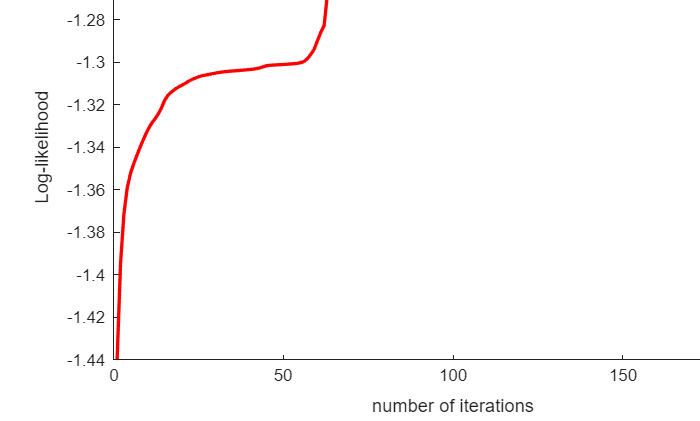

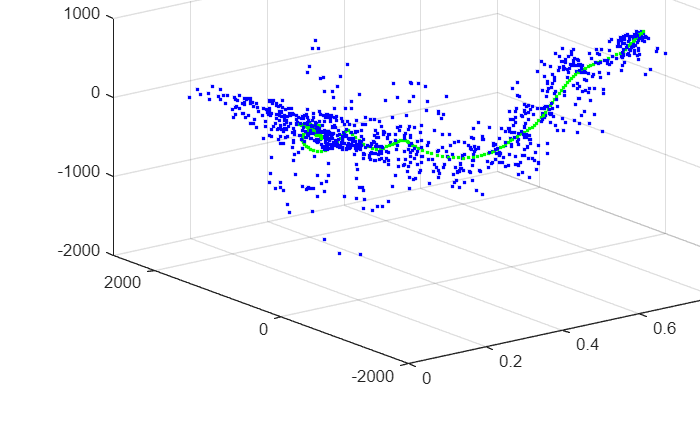

fGMR = dmp.fittingWithGMR() ;

trajGMR = dmp.forcing2Trajectory(fGMR);

Spatial plot

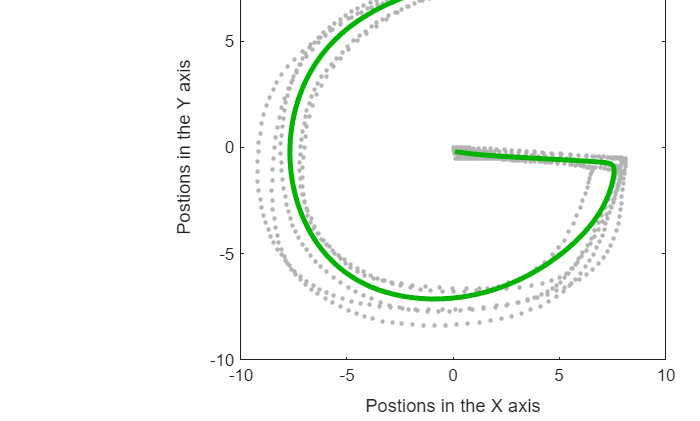

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajGMR(1,:),trajGMR(2,:),'-','linewidth',3,'color',[0 .7 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
axis equal; axis square; hold off

--------------------------------------------------------

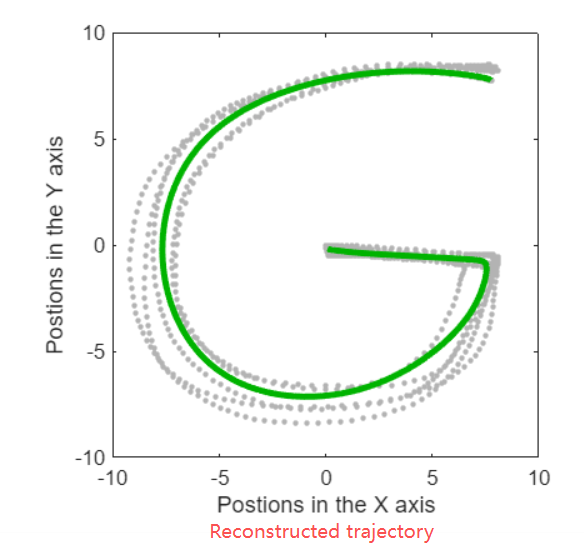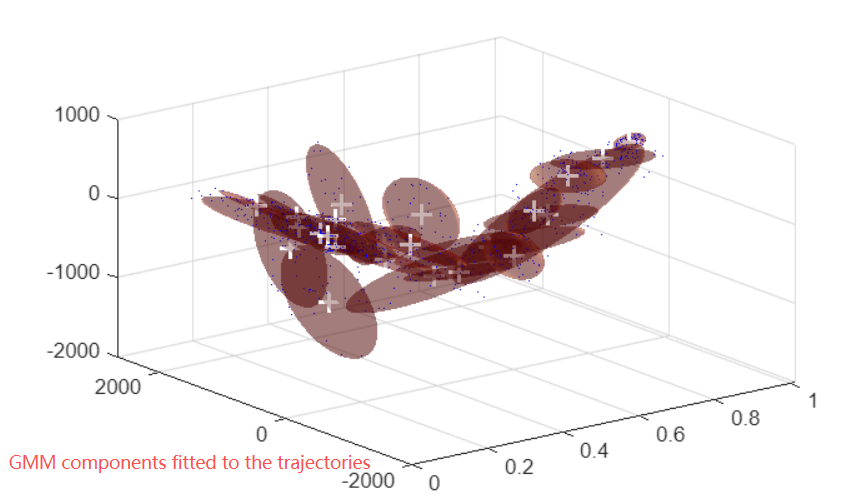

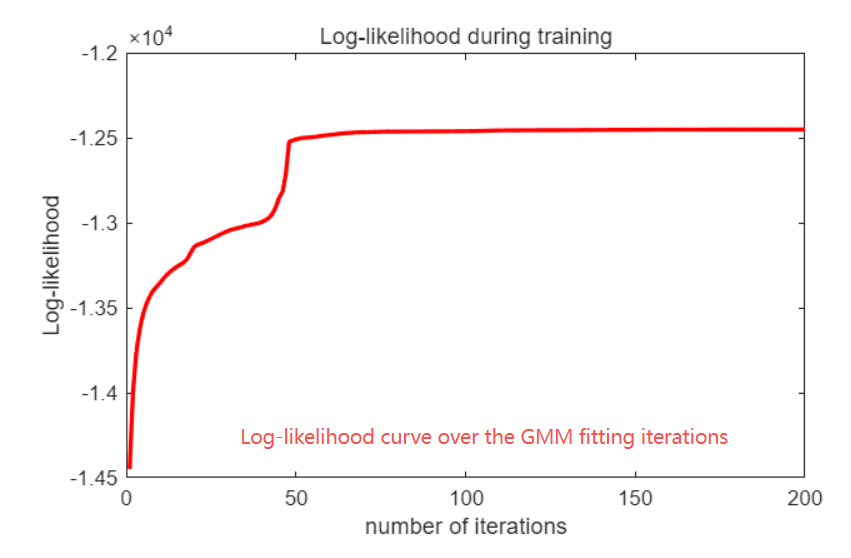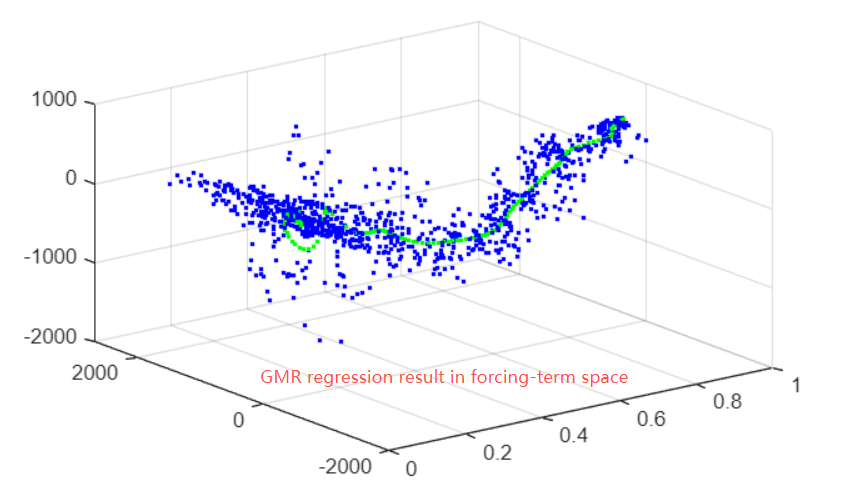

--------------------------------------------------------

### Part 3: Evaluation (15 marks)

- Evaluate the proposed enhanced DMPs method by comparing the differences between the original DMPs and the enhanced method in Cartesian space coordinates.

- The successful results should demonstrate comparative errors between two different methods.

- Complete the comparison using MATLAB code or functions to quantify and evaluate your results.

- When completing this part, please use the plot function in MATLAB, or other suitable methods, to visualise your comparison results and provide analysis of them. Please note that failing to conduct the comparison rigorously in this section will also affect your score in Task 2, as the analysis of all models is carried out here.

- Save the best trajectory from your robot learning as `LearnedTrajectory.mat` for use in future tasks.

Below is a loop to generate an appropriate figure to view your results. Use this as a starting point to demonstrate the differences between original and enhanced DMPs (which you explored in Tasks 1 and 2 respectively).

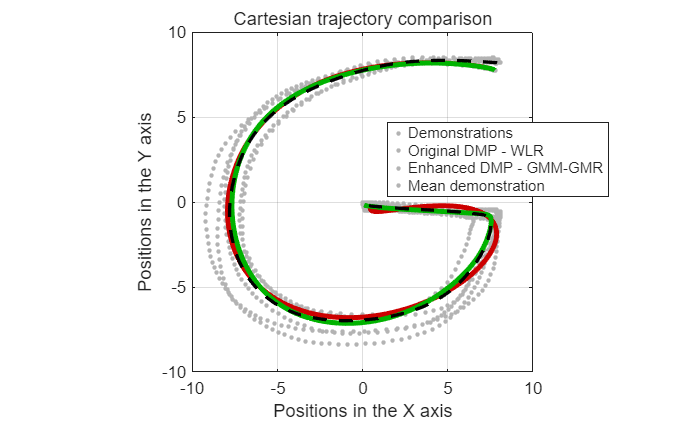

%% Part 3: Evaluation between Original DMP and GMM-GMR Enhanced DMP

% Resample all demonstrations to the same length as the reconstructed trajectories
numDim = size(trajWLR, 1);
demoResampled = zeros(numDim, nbData, nbDemos);

for n = 1:nbDemos
    demoResampled(:,:,n) = spline( ...
        1:size(demos_in{n}.pos, 2), ...
        demos_in{n}.pos, ...
        linspace(1, size(demos_in{n}.pos, 2), nbData) ...
    );
end

% Compute the mean demonstration as a reference trajectory
meanDemo = mean(demoResampled, 3);

%% Figure 1: Cartesian trajectory comparison
figure;
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:), '.', ...
        'markersize', 8, 'color', [.7 .7 .7]); 
    hold on;
end

plot(trajWLR(1,:), trajWLR(2,:), '-', ...
    'linewidth', 3, 'color', [.8 0 0]);

plot(trajGMR(1,:), trajGMR(2,:), '-', ...
    'linewidth', 3, 'color', [0 .7 0]);

plot(meanDemo(1,:), meanDemo(2,:), '--k', ...
    'linewidth', 2);

xlabel('Positions in the X axis');
ylabel('Positions in the Y axis');
title('Cartesian trajectory comparison');
legend('Demonstrations', 'Original DMP - WLR', ...
    'Enhanced DMP - GMM-GMR', 'Mean demonstration', ...
    'Location', 'best');

axis equal;
axis square;
grid on;
hold off;


%% Compute Euclidean errors against each demonstration
errWLR_eachDemo = zeros(nbDemos, nbData);
errGMR_eachDemo = zeros(nbDemos, nbData);

for n = 1:nbDemos
    diffWLR = trajWLR - demoResampled(:,:,n);
    diffGMR = trajGMR - demoResampled(:,:,n);

    errWLR_eachDemo(n,:) = sqrt(sum(diffWLR.^2, 1));
    errGMR_eachDemo(n,:) = sqrt(sum(diffGMR.^2, 1));
end

% Mean error at each time step
errWLR_time = mean(errWLR_eachDemo, 1);
errGMR_time = mean(errGMR_eachDemo, 1);

% Summary error metrics
meanErrWLR = mean(errWLR_eachDemo(:));
meanErrGMR = mean(errGMR_eachDemo(:));

rmseWLR = sqrt(mean(errWLR_eachDemo(:).^2));
rmseGMR = sqrt(mean(errGMR_eachDemo(:).^2));

maxErrWLR = max(errWLR_eachDemo(:));
maxErrGMR = max(errGMR_eachDemo(:));

stdErrWLR = std(errWLR_eachDemo(:));
stdErrGMR = std(errGMR_eachDemo(:));

%% Figure 2: Error over time
figure;
plot(1:nbData, errWLR_time, 'r-', 'LineWidth', 2);
hold on;
plot(1:nbData, errGMR_time, 'g-', 'LineWidth', 2);

xlabel('Time step');
ylabel('Mean Euclidean error');
title('Error comparison over time');
legend('Original DMP - WLR', 'Enhanced DMP - GMM-GMR', ...
    'Location', 'best');

grid on;
hold off;


%% Figure 3: Error metrics bar chart
errorMetrics = [meanErrWLR, rmseWLR, maxErrWLR, stdErrWLR;
                meanErrGMR, rmseGMR, maxErrGMR, stdErrGMR];

figure;
bar(errorMetrics);

set(gca, 'XTickLabel', {'Original DMP - WLR', 'Enhanced DMP - GMM-GMR'});
ylabel('Error value');
title('Quantitative error comparison');
legend('Mean Error', 'RMSE', 'Maximum Error', 'Standard Deviation', ...
    'Location', 'best');

grid on;


%% Display numerical results in MATLAB Command Window
Method = {'Original DMP - WLR'; 'Enhanced DMP - GMM-GMR'};
MeanError = [meanErrWLR; meanErrGMR];
RMSE = [rmseWLR; rmseGMR];
MaxError = [maxErrWLR; maxErrGMR];
StdError = [stdErrWLR; stdErrGMR];

ResultTable = table(Method, MeanError, RMSE, MaxError, StdError)

ResultTable = 2×5 table
              Method              MeanError     RMSE     MaxError    StdError
    __________________________    _________    ______    ________    ________

    {'Original DMP - WLR'    }      1.515      1.9026     4.9118      1.1515 
    {'Enhanced DMP - GMM-GMR'}     1.4233      1.8408     4.6147      1.1679 



%% Save the better trajectory for future tasks
if rmseGMR <= rmseWLR
    LearnedTrajectory = trajGMR;
    BestMethod = 'Enhanced DMP with GMM-GMR';
else
    LearnedTrajectory = trajWLR;
    BestMethod = 'Original DMP with WLR';
end

save('LearnedTrajectory.mat', ...
    'LearnedTrajectory', ...
    'BestMethod', ...
    'trajWLR', ...
    'trajGMR', ...
    'meanDemo', ...
    'ResultTable');

disp(['Best trajectory saved using: ', BestMethod]);

Best trajectory saved using: Enhanced DMP with GMM-GMR


### Demonstrate your results using figures, graphs or tables below with text, comparing the trajectories generated by original vs improved DMPs (max. 500 words):

--------------------------------------------------------

This section evaluates the original DMP with locally weighted linear regression (WLR) and the enhanced DMP with GMM-GMR in Cartesian space. To ensure a fair comparison, all demonstrations were resampled to 200 points, and the mean demonstration was used as a reference trajectory. The reconstruction performance was measured using Euclidean distance between each generated trajectory and the resampled demonstrations.

Figure 1 compares the demonstrations with the reconstructed trajectories. The grey points show the five demonstrations, the red curve shows the original DMP-WLR result, the green curve shows the enhanced DMP-GMM-GMR result, and the black dashed line shows the mean demonstration. Both methods reproduce the overall motion pattern, but the GMM-GMR trajectory follows the central trend more closely, especially around the upper arc and final inward segment. This indicates better generalisation from multiple demonstrations.

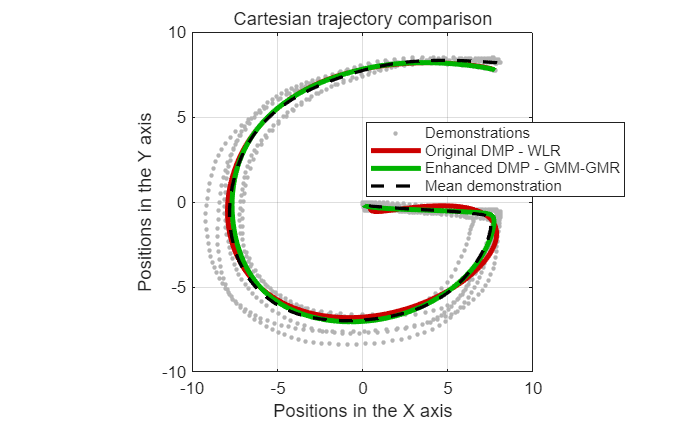

**Figure 1. Cartesian trajectory comparison between demonstrations, original DMP-WLR, enhanced DMP-GMM-GMR and mean demonstration.**

To further compare the two methods, the mean Euclidean error was calculated at each time step. Figure 2 shows that the enhanced GMM-GMR method generally produces a lower error than the original WLR method over most of the trajectory. The difference is especially clear around time steps 80–100 and 135–155, where the original DMP shows larger error peaks. At the final part of the trajectory, the enhanced method also converges to a lower error value. Although both methods show similar error trends, the GMM-GMR curve remains below the WLR curve for a large portion of the movement, indicating more stable reconstruction performance.

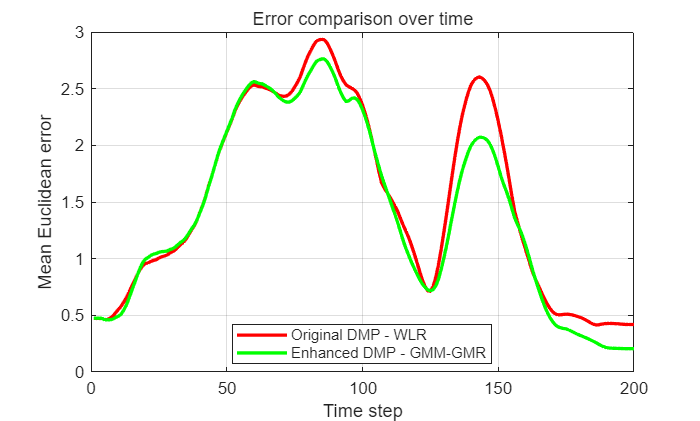

**Figure 2. Mean Euclidean error over time for original DMP-WLR and enhanced DMP-GMM-GMR.**

The quantitative error results are shown in Figure 3 and Table 1. The original DMP-WLR method produced a mean error of 1.5150 and an RMSE of 1.9026, while the enhanced DMP-GMM-GMR method reduced these values to 1.4094 and 1.8346 respectively. This corresponds to a reduction of approximately 6.97% in mean error and 3.57% in RMSE. The maximum error was also reduced from 4.9118 to 4.5478, showing that the enhanced method decreased the largest deviation along the trajectory. The standard deviation of the error is slightly higher for the enhanced method, increasing from 1.1515 to 1.1750, which suggests that although the overall error is lower, the error distribution is not uniformly reduced at every time step.

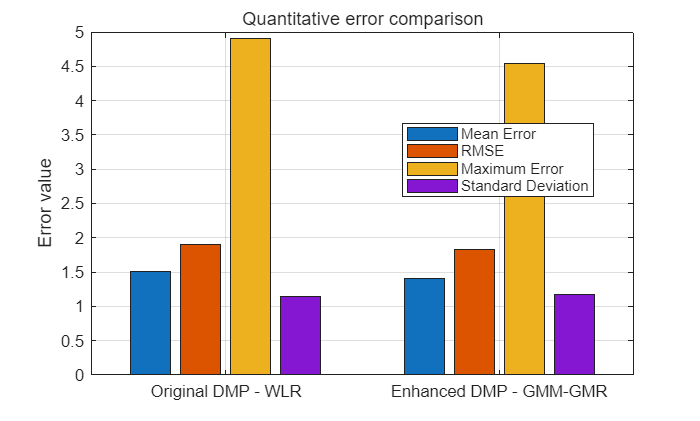

**Figure 3. Quantitative error comparison between original DMP-WLR and enhanced DMP-GMM-GMR.**

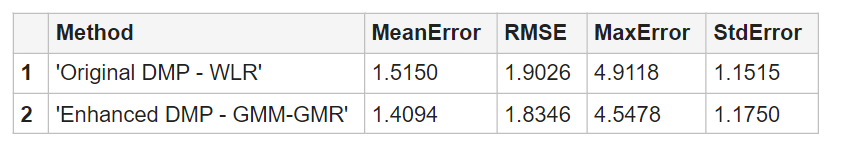

**Table 1. Numerical error comparison between original and enhanced DMP methods.**

Overall, the enhanced DMP-GMM-GMR method performed better than the original DMP-WLR method, with lower mean error, RMSE and maximum error. This shows that using GMM-GMR to model and regress the nonlinear forcing term improves trajectory generalisation from multiple demonstrations. Therefore, the GMM-GMR reconstructed trajectory was selected as the best learned trajectory and saved as `LearnedTrajectory.mat` for the later kinematic and dynamic simulations.

--------------------------------------------------------

## Task 3: Kinematic Simulation (7 marks)

- Save the new trajectory `LearnedTrajectory.mat `with the best performance, as evaluating in Task 2, Part 3, as a time series in the file `‘SimData.mat’` using the code provided to facilitate further simulation.

- Please open the Simulink project **RobotSimulation.slx**, which consists of a 2‑DOF planar robot model with two 10 m‑long links. By clicking **Run** in Simulink, you will see a static planar robot and an orange trajectory automatically loaded by the `initFcn`.

- To simulate the robot’s movement in Simscape, you need to complete the `inverse_kinematics` function block located in the Trajectory Input subsystem of the project. Please use mathematical notation (see Task 1 for how to insert equations) to show the function you implemented in this block for later analysis.

- Run the simulations, take screenshots of the results shown in the scopes, and provide your analysis of the simulation outcomes below.

#### ***Useful materials for this Part include:***

- The save function documentation: [Save variables from workspace to file - MATLAB save - MathWorks United Kingdom](https://uk.mathworks.com/help/matlab/ref/save.html)

- The tutorial material on Robot Control

whos -file LearnedTrajectory.mat

  Name                   Size             Bytes  Class     Attributes

  BestMethod             1x25                50  char                
  LearnedTrajectory      2x200             3200  double              
  ResultTable             -                2389  table               
  meanDemo               2x200             3200  double              
  trajGMR                2x200             3200  double              
  trajWLR                2x200             3200  double              



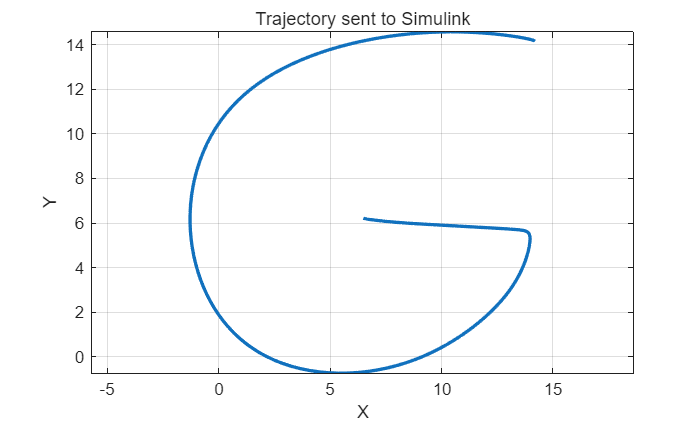

%% Task 3: Prepare SimData

clear; clc; close all;

S = load("LearnedTrajectory.mat");


bestTraj = S.LearnedTrajectory;

X_pos = bestTraj(1,:)';
Y_pos = bestTraj(2,:)';


X_offset = 6.4;
Y_offset = 6.4;

retrievedTraj = [X_pos + X_offset, Y_pos + Y_offset];


retrievedTraj_time = linspace(0, 120, size(retrievedTraj, 1))';

dataset = timeseries(retrievedTraj, retrievedTraj_time, 'Name', 'SimData');

save("SimData.mat", "dataset", "-v7.3");


figure;
plot(retrievedTraj(:,1), retrievedTraj(:,2), 'LineWidth',2);
title('Trajectory sent to Simulink');
xlabel('X'); ylabel('Y');
axis equal; grid on;

### Provide screenshots and your analysis supporting your results (max. 400 words): 

------------------------------------------------------

The best trajectory selected from Task 2 was saved as `LearnedTrajectory.mat` and then converted into a Simulink-compatible time series named `SimData.mat`. The learned Cartesian trajectory was shifted to ensure that it remained inside the reachable workspace of the 2-DOF planar robot, where both links have a length of 10 m. Figure 4 shows the final trajectory sent to Simulink, which keeps the expected G-shaped path.

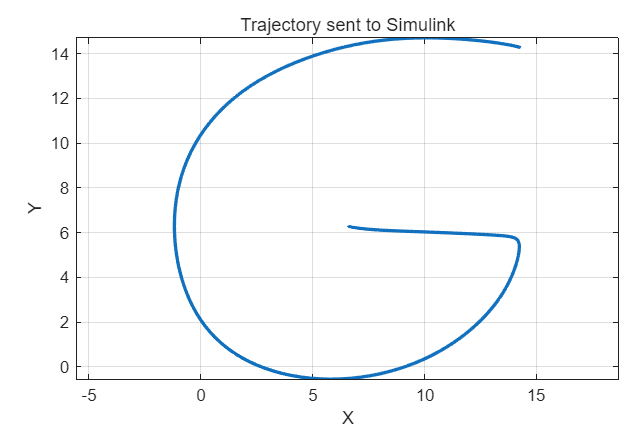

**Figure 4. Learned trajectory converted into Simulink time-series input**

To enable the planar robot to follow this Cartesian trajectory, an inverse kinematics function was implemented in the Trajectory Input subsystem. For a target point $(x,y)$, with link lengths , $L_1=L_2=10$the joint angles were calculated using:


$$D = \frac{x^2 + y^2 - L_1^2 - L_2^2}{2L_1L_2}$$



$$q_2 = {atan2}\left(\sqrt{1-D^2},D\right)$$



$$q_1 = {atan2}(y,x) - {atan2}\left(L_2\sin(q_2),L_1 + L_2\cos(q_2)\right)$$


These equations define the inverse kinematics model for the 2-DOF planar robot. For each desired Cartesian point $(x,y)$, the value $D$ is first calculated using the cosine rule based on the two link lengths $L_1$ and $L_2$. The second joint angle $q_2
$ is then obtained from $D$, while the first joint angle $q_1$ is calculated from the geometric relationship between the target point and the two robot links. In this simulation, both links are 10 m long, and the calculated joint angles are used as the desired joint positions for the robot to follow the learned trajectory.

Figure 5 shows the XY Graph result. The trajectory of pure kinematic simulation is consistent with the trajectory stored in SimData.mat. This is because the Cartesian points from SimData.mat are converted into desired joint angles through the inverse kinematics block, and the end-effector position is then reconstructed using forward kinematics. Since the joints are actuated in Motion mode during the kinematic simulation, the robot follows the prescribed joint trajectory directly. Therefore, the XY Graph reproduces the same G-shaped path as the input trajectory from SimData.mat.

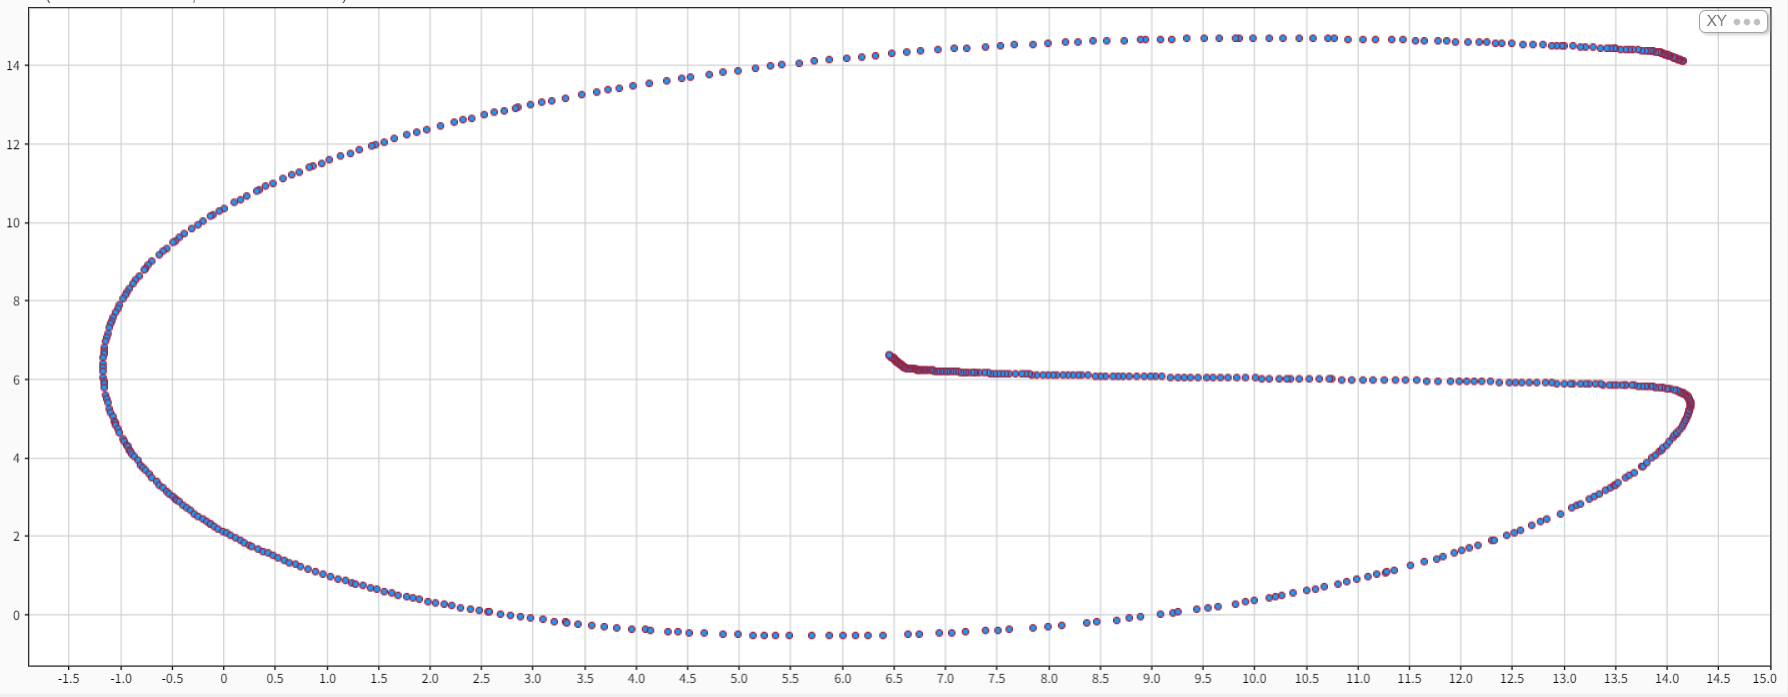

**Figure 5. XY Graph showing the planar robot tracking the learned trajectory**

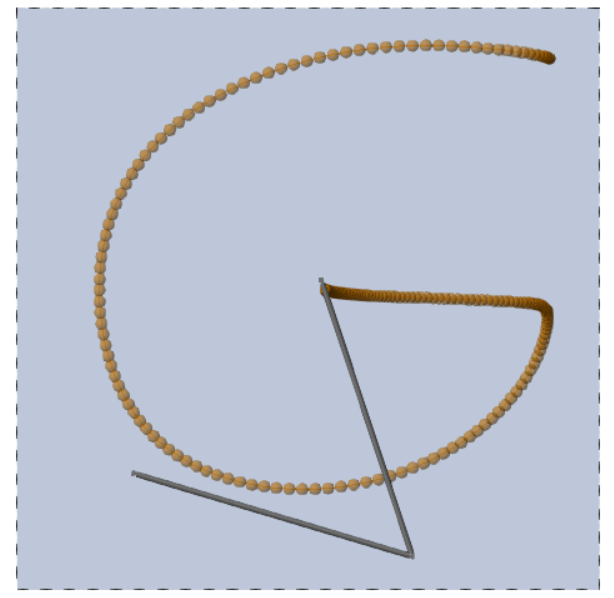

**Figure 6. Simscape visualisation of the 2-DOF planar robot following the G-shaped trajectory**

The joint scope results in Figure 7 show that both joints produce continuous position and velocity responses during the movement. However, noticeable acceleration peaks appear at the beginning of the simulation and near sharp curvature changes in the trajectory. These peaks are mainly caused by numerical differentiation and rapid changes in the reference path. Since this task only uses kinematic simulation, no dynamic controller is applied to smooth the motion. Overall, the simulation demonstrates that the learned trajectory can be successfully transferred from the robot learning stage into the 2-DOF planar robot model, providing a suitable reference for the following dynamic control task.

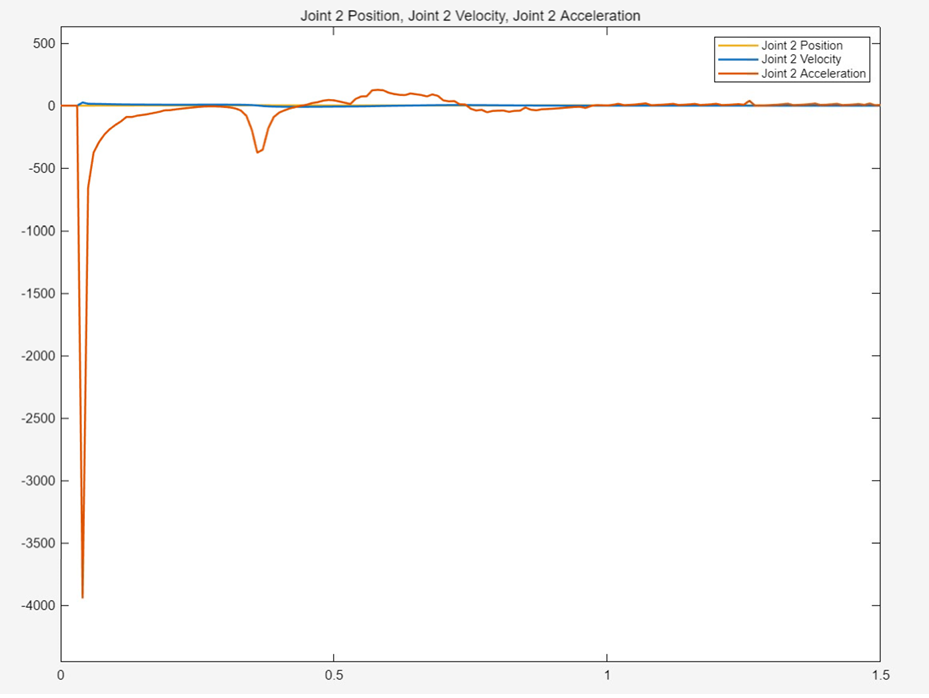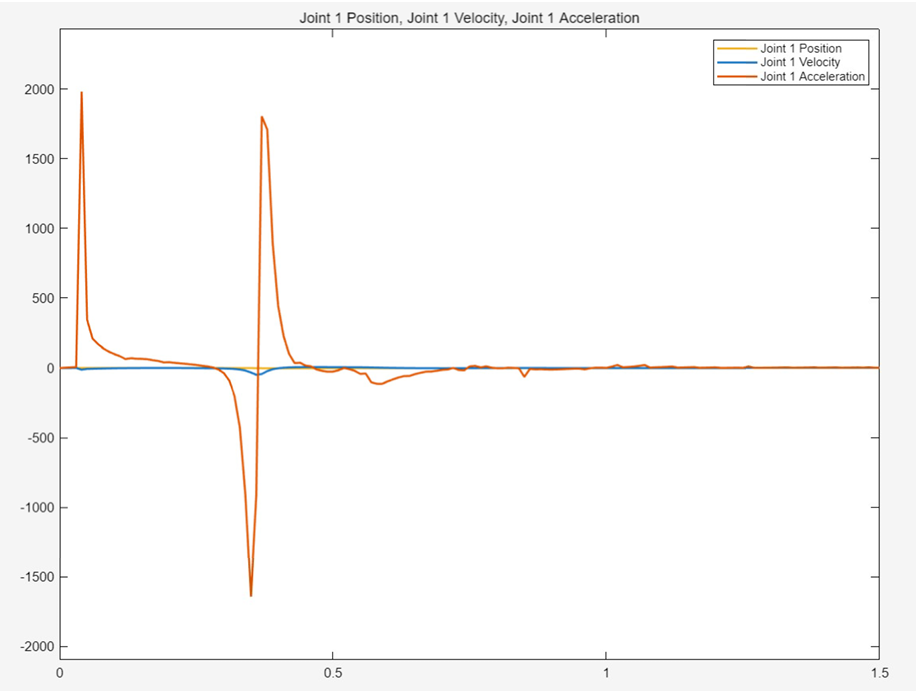

**Figure 7. Joint 1 and Joint 2 position, velocity and acceleration responses**

-----------------------------------------------------

## Task 4: Dynamics Simulation (8 marks)

From the kinematic simulation in Task 3, the end‑effector trajectory is reconstructed using inverse and forward kinematics. However, based on your analysis, the planar robot requires better control—specifically, improved trajectory tracking using a PD controller. Please optimise the planar robot by completing the following dynamics simulation tasks.

- In the previous simulation, the two joints were actuated in Motion mode. To enable dynamic simulation, first change the actuation of both revolute joints in Robot subsystem to Torque mode by setting `Actuation > Torque` to **Provided by Input**, and change `Actuation > Motion` to **Automatically Computed**.

- You should begin with the `jointPos2Vel` function block in the Trajectory Input subsystem to obtain the reference joint velocities required for the PD controller. Then paste your completed MATLAB in the function below as plain text (avoid execution) in monospaced font.

- The rigid‑body parameters are defined within the Simscape Multibody model. You can view them by checking the inertia properties of each planar robot link in the Multibody Explorer. Using the **model‑based portion** and **position‑tracking control** approach, design a PD controller to generate the torque inputs for each revolute joint. Failure to incorporate the model‑based component into your controller design will result in a deduction of marks for this task.

- After building the controller, connect its output to the torque‑actuated joints of the planar robot. Please **paste clear screenshots** of your revised Simulink model below for reference. Then rerun the simulation to validate the controller’s performance.

- Provide your reasoning process for building a functional PD controller, including justification for the chosen parameters. Analyse the simulation results shown in the Scopes and the XY Graph, and compare them with the results obtained from the pure kinematic simulation.

#### ***Useful materials for this Part include:***

- Lecture notes on Position Tracking Control and Model Based Portion Modelling

- Tutorial on Robot Control

load("SimData.mat");

x0 = dataset.Data(1,1);
y0 = dataset.Data(1,2);

L1 = 10;
L2 = 10;

D = (x0^2 + y0^2 - L1^2 - L2^2) / (2*L1*L2);
D = min(max(D,-1),1);

q2_0 = atan2(sqrt(1-D^2), D);
q1_0 = atan2(y0,x0) - atan2(L2*sin(q2_0), L1 + L2*cos(q2_0));

fprintf("Initial q1 = %.4f rad\n", q1_0);

Initial q1 = 0.7841 rad


fprintf("Initial q2 = %.4f rad\n", q2_0);

Initial q2 = 0.0000 rad


fprintf("Initial q1 = %.2f deg\n", rad2deg(q1_0));

Initial q1 = 44.93 deg


fprintf("Initial q2 = %.2f deg\n", rad2deg(q2_0));

Initial q2 = 0.00 deg



load("SimData.mat")

dataset.Time(1)

ans = 0

dataset.Time(end)

ans = 120

length(dataset.Time)

ans = 200

disp(size(retrievedTraj, 1))

   200



### Describe your model and compare your results below (max. 400 words):

--------------------------------------------------------

To obtain the reference joint velocities required for the PD controller, the jointPos2Vel function block is built as:

`function [qdot1, qdot2] = jointPos2Vel(q1, q2, Ts)`

`persistent q1_prev q2_prev`

`if isempty(q1_prev)`

`    q1_prev = q1;`

`    q2_prev = q2;`

`end`

`qdot1 = (q1 - q1_prev) / Ts;`

`qdot2 = (q2 - q2_prev) / Ts;`

`q1_prev = q1;`

`q2_prev = q2;`

`end`

It receives the desired joint positions $q_1$ and $q_2$ from the inverse kinematics block and estimates their velocities using a backward difference method. The persistent variables store the joint positions from the previous time step, allowing the function to compute $\dot{q}_1 = \frac{q_1 - q_{1,\mathrm{prev}}}{T_s}$ and $\dot{q}_2 = \frac{q_2 - q_{2,\mathrm{prev}}}{T_s}$. These velocity references are then used by the controller to form the derivative tracking error.

The PD controller was designed using a model-based position-tracking approach. The rigid-body parameters were taken from the Simscape Multibody model: both links have a mass of $1\,\mathrm{kg}$, inertia $[1,1,1]\,\mathrm{kg\,m^2}$, and centre of mass at $[0,0,0]$. Therefore, $I_{1zz}=I_{2zz}=1\,\mathrm{kg\,m^2}$ was used. Since joint 1 must rotate both links and the mass of link 2 at $L_1=10\,\mathrm{m}$, its effective inertia was modelled as $M_{11}=I_{1zz}+I_{2zz}+m_2L_1^2$, while $M_{22}=I_{2zz}$ was used for joint 2. The controller computes $v=K_pe+K_d\dot{e}$, and the torque is generated by $\tau=Mv$. Different gains and torque limits were applied because joint 1 has much larger effective inertia than joint 2.

The revised Simulink model is as follows:

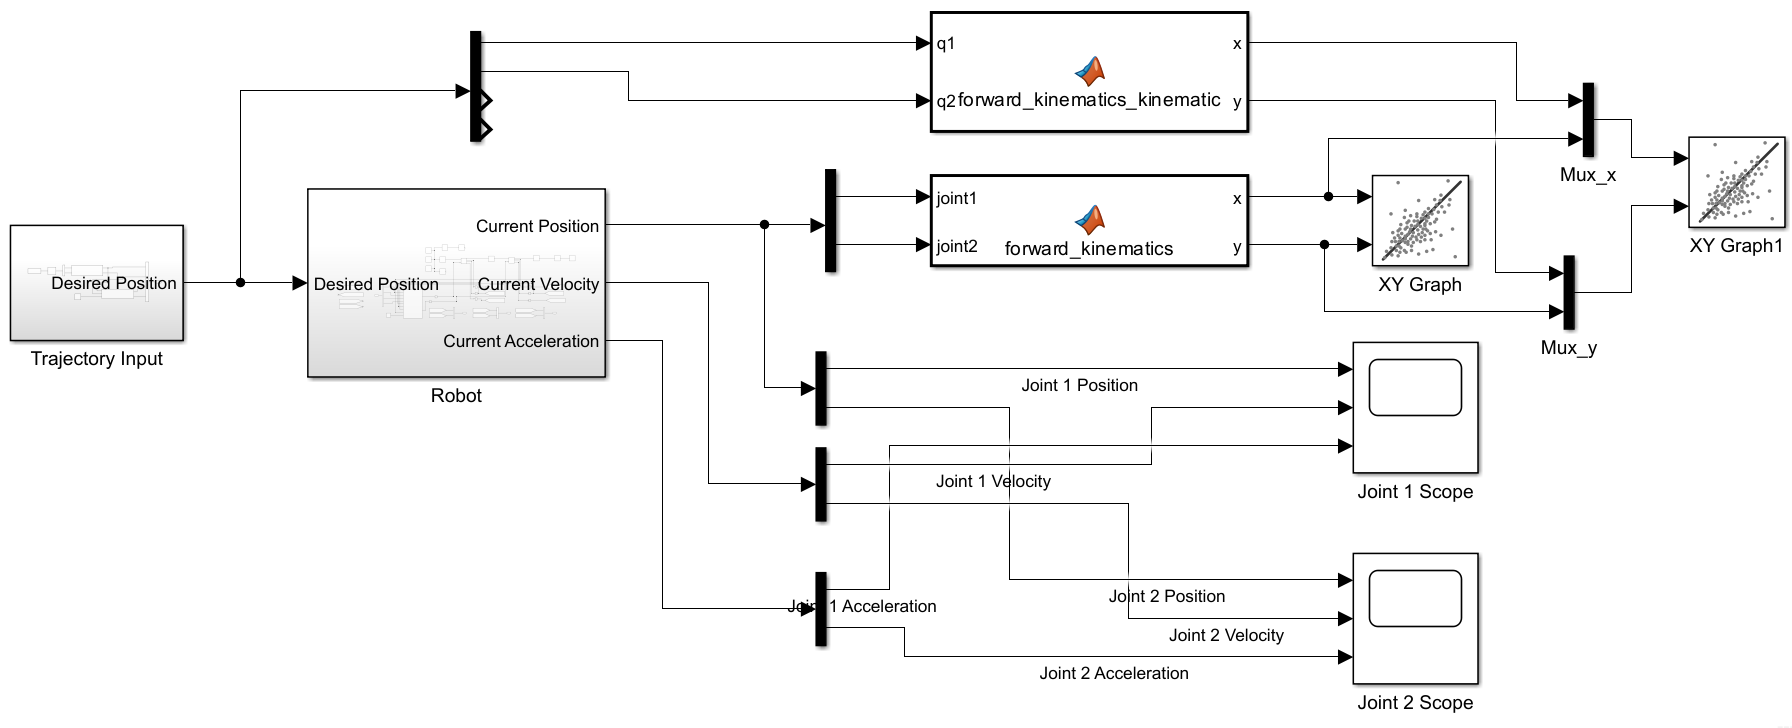 

**Figure 8. The parent Simulink model**

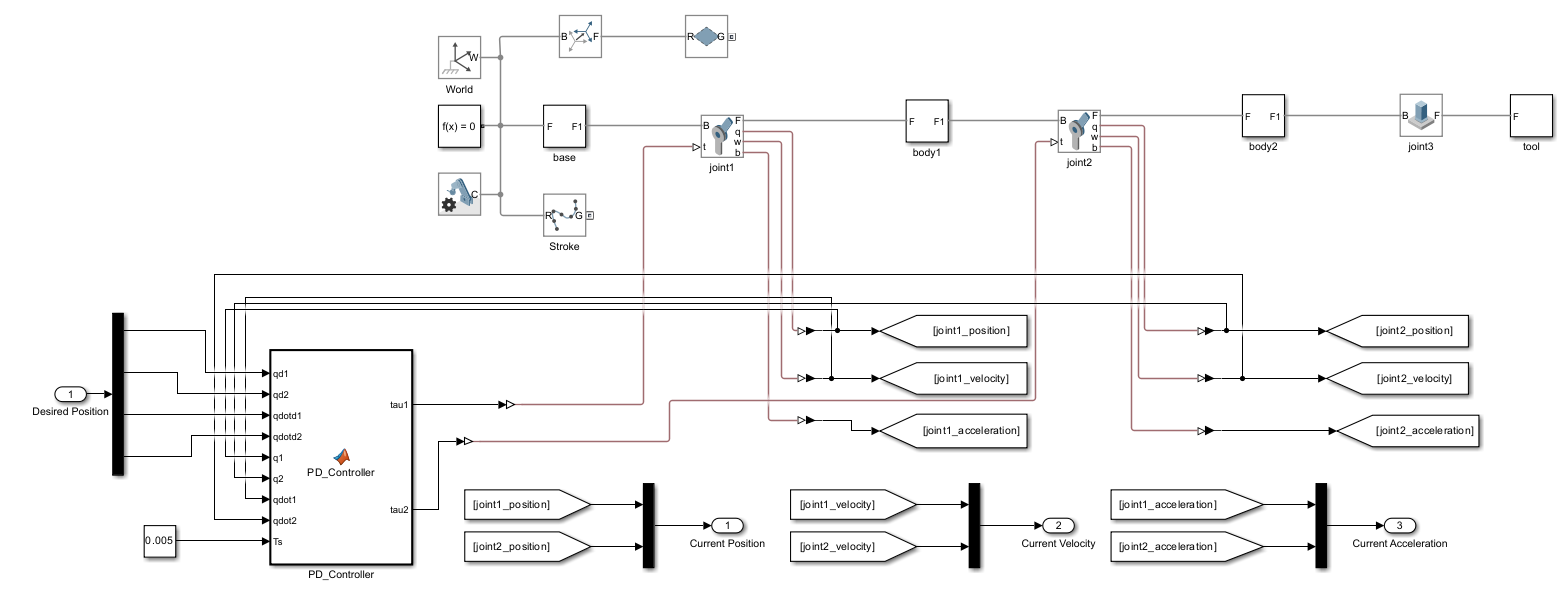

**Figure 9. The Robot subsystem**

The controller parameters were selected by balancing tracking accuracy, motor protection and smoothness. Increasing $K_p$ improves position tracking, but too large a value produces high acceleration peaks and vibration, which may damage the actuator in a real system. Joint 1 was assigned a larger gain because it carries the effective inertia of both links, while $K_{p2}$ was kept small because joint 2 has much lower inertia and became unstable when its gain was too high. The derivative gains were not chosen arbitrarily; they were calculated using the critical damping relation $K_d = 2\sqrt{K_pM}$. This provides physically motivated damping according to the effective joint inertia and helps reduce overshoot. The trajectory duration in `SimData.mat` was also tuned. Very long durations, such as 500 s, reduce the required torque and acceleration but are inefficient, while shorter durations, such as 20 s, require large control effort and cause vibration. A duration of 120 s was selected as a practical compromise. With $K_{p1}=400$, $K_{p2}=10$, and $K_d$ computed from the damping formula, the robot achieved acceptable tracking while limiting acceleration peaks and the results are shown in figure 10.

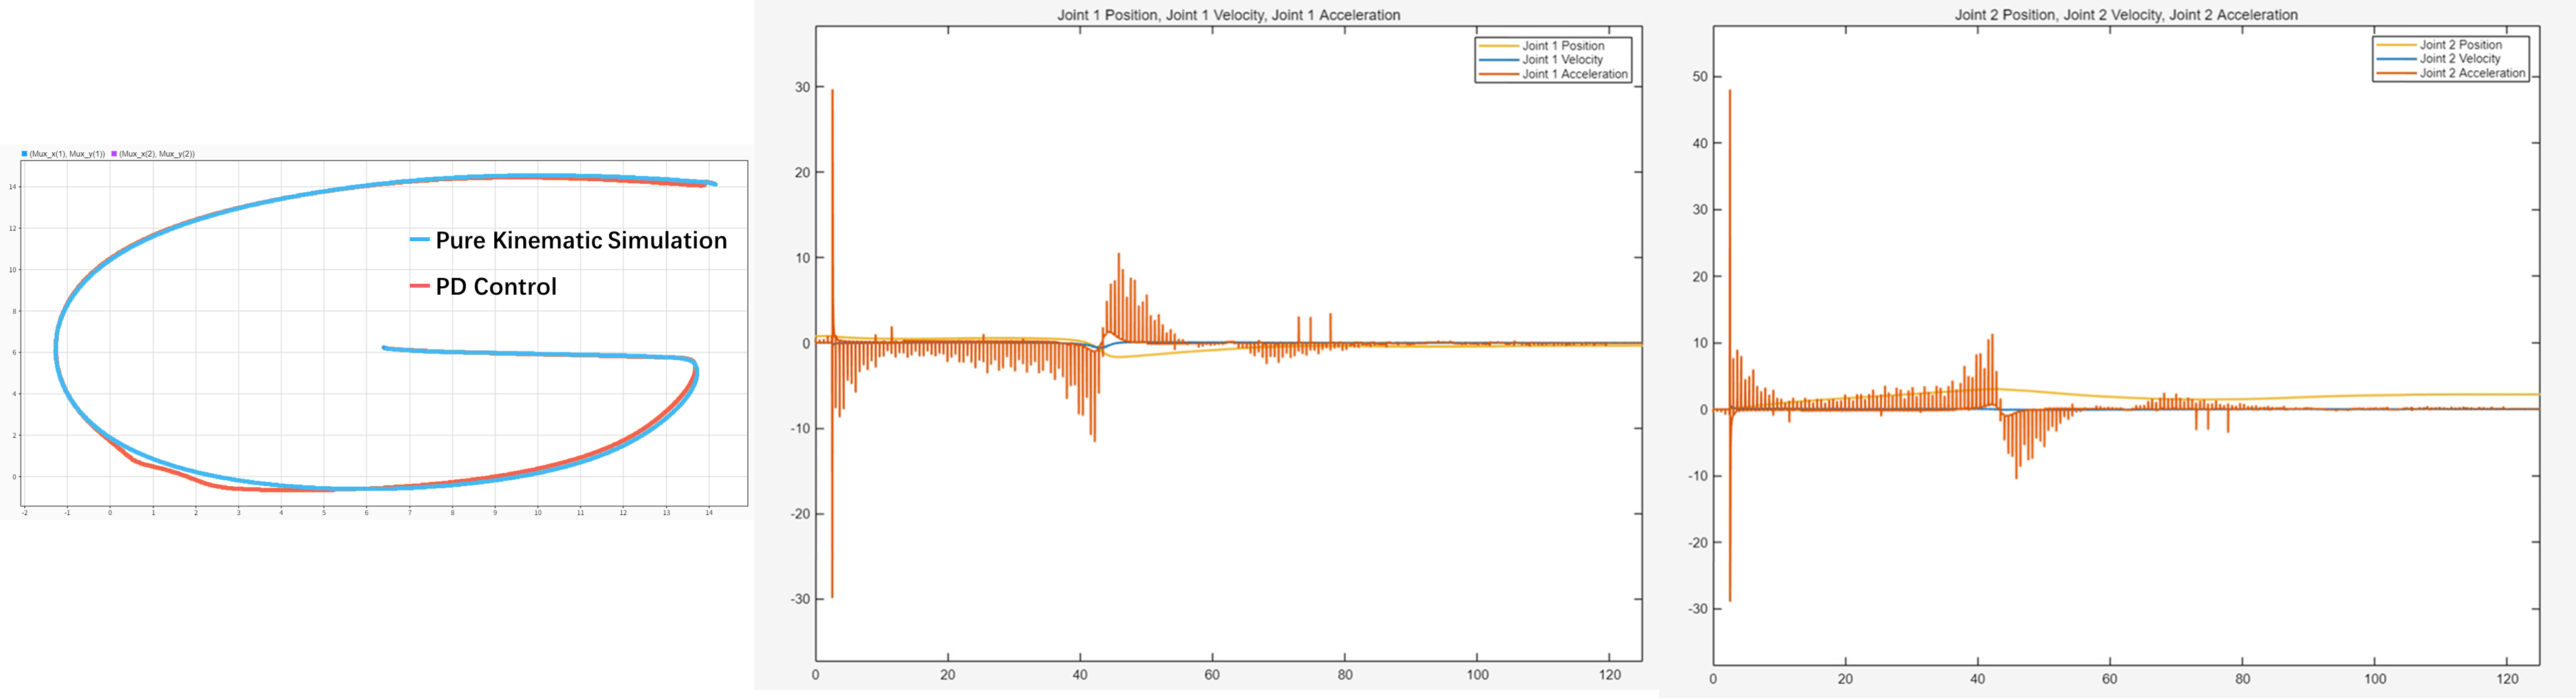

**Figure 10. The results with 120 SimData trajectory duration**

The XY graph demonstrates excellent tracking performance under these parameters, with minimal peaks observed on the oscilloscopes of the two joints. Velocity and position are stable, and the maximum acceleration is within the range of -50 rad/s² to 50 rad/s². Figure 11 and Figure 12 show the other situations.

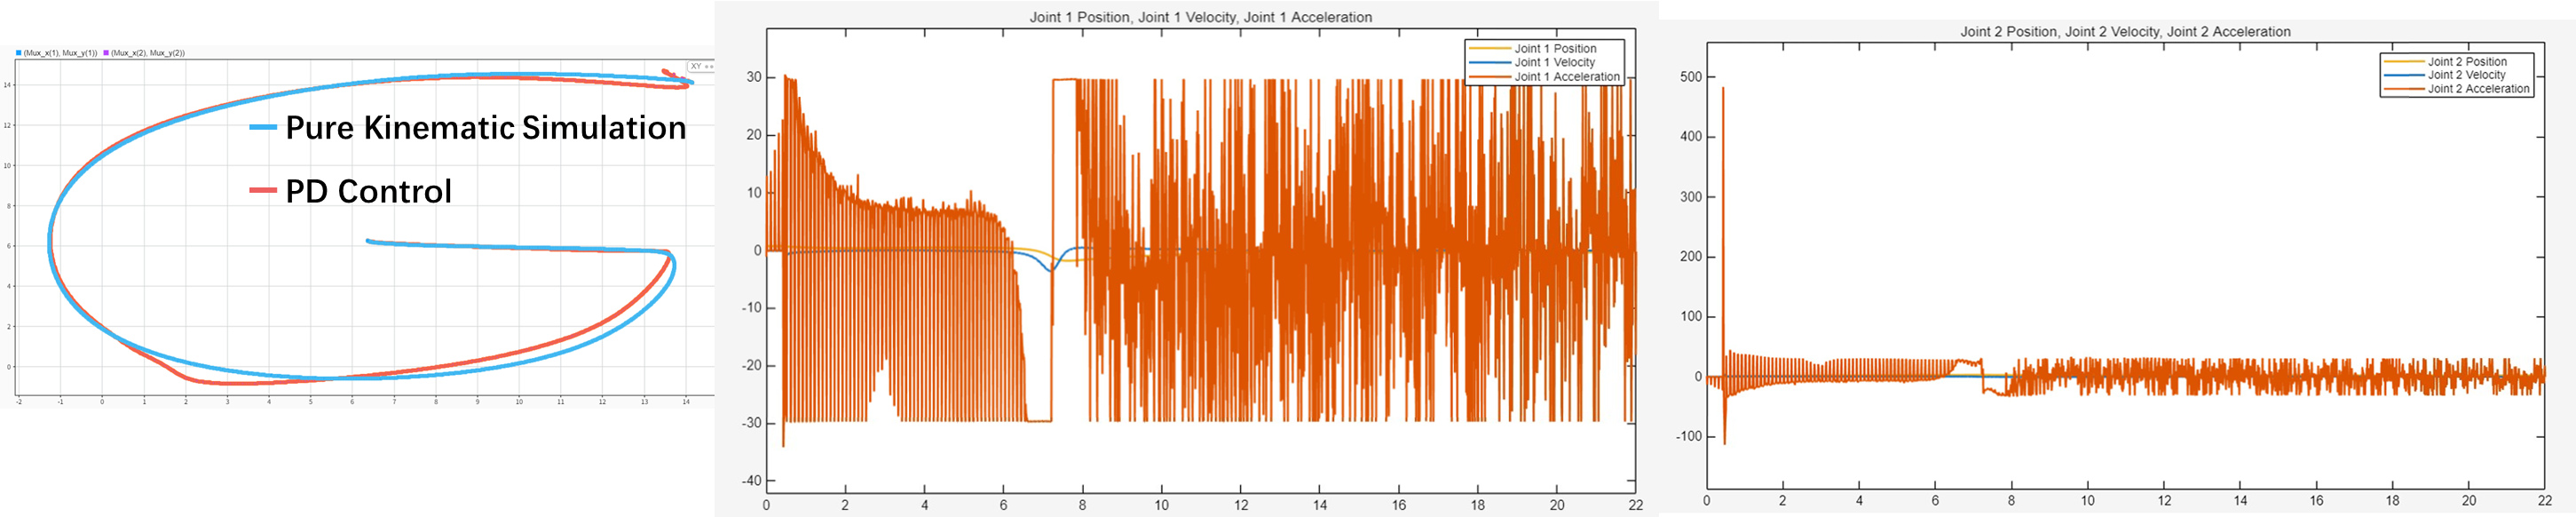

**Figure 11. The results with 20 SimData trajectory duration (**$K_{p1}$=8000, $K_{p2}$=900**)**

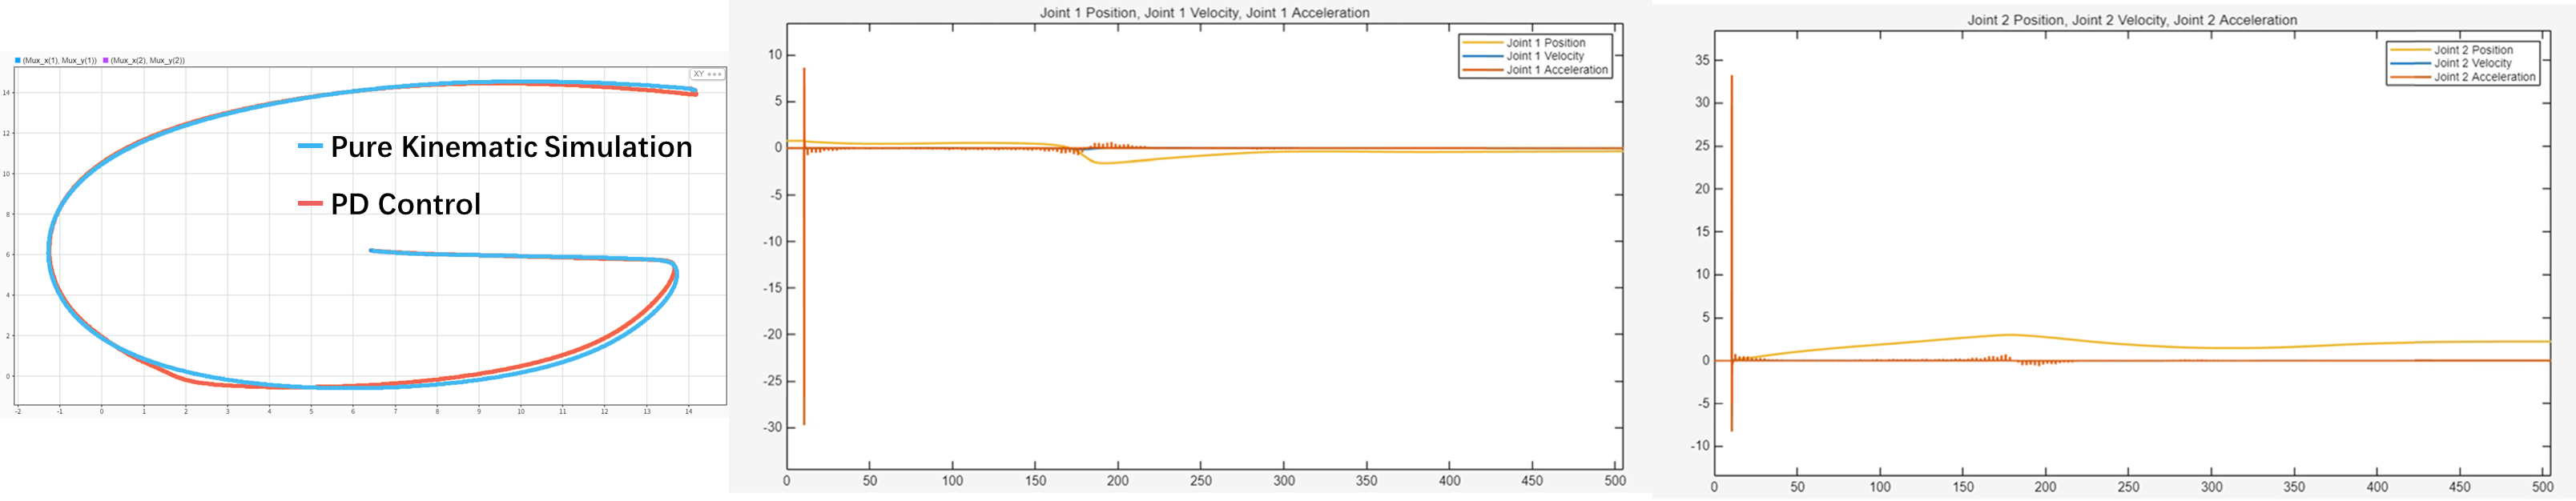

**Figure 12. The results with 20 SimData trajectory duration(**$K_{p1}$=30, $K_{p2}$=2**)**

--------------------------------------------------------

## - End of document -

Please check the following before exporting your MLX file to PDF:

- Ensure that all code sections run successfully.

- Double‑check that all required screenshots are clearly inserted.

- Do not omit any results that are required for marking and located in other files.